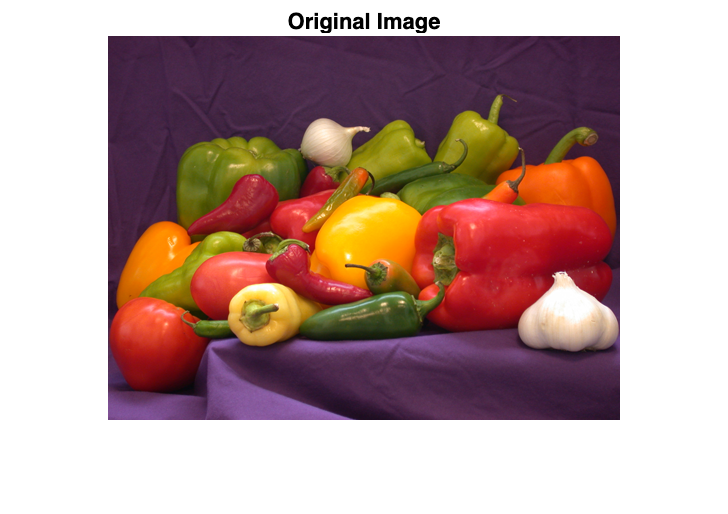

% Image Processing and Visualization
%
% Contents
% 1. Introduction
% 2. Reading and Displaying the Image
% 3. Applying Image Processing Filter/Effect
% 4. Displaying the Result
% 5. Saving the Result
%
% 1. Introduction
% This script goes though basic image processing operations in MATLAB. 
% Such as reading an image, applying a filter, displaying the original and processed images, and saving the result.
%
% BONUS
% Using Livescript controls it is possible to select images and apply a
% filter with a UI. We can also save that image. 
% 
%The code was also uploaded to Github

%% 2. Reading and Displaying the Image

img = imread('peppers.png'); 
figure;
imshow(img);
title('Original Image');

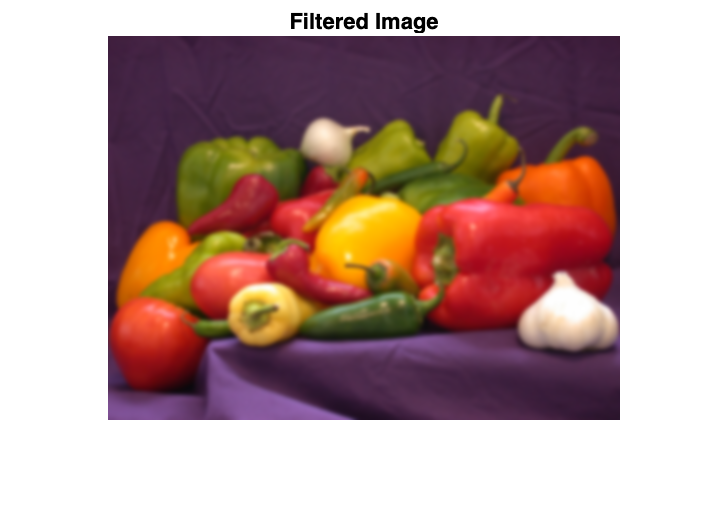





%% 3. Applying Image Processing Filter/Effect
imgFiltered = imgaussfilt(img, 2);


%% 4. Displaying the Blurred Image
figure;
imshow(imgFiltered);
title('Gaussian Blurred Image');

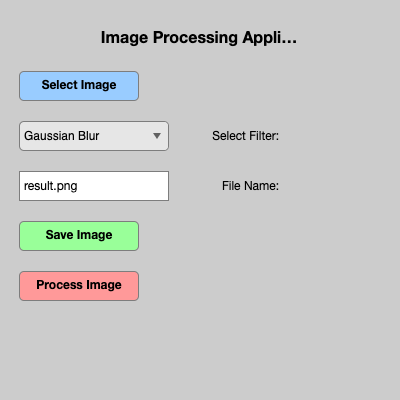




%% 5. Saving the Result
imwrite(imgFiltered, 'result.png');

uiFigure = uifigure('Name', 'Enhanced Image Processing', 'Color', [0.8, 0.8, 0.8], 'Position', [100 100 400 400]);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%BONUS  Start of UI

lblTitle = uilabel(uiFigure, ...
    'Text', 'Image Processing Application', ...
    'Position', [100, 350, 200, 30], ...
    'FontSize', 16, ...
    'FontWeight', 'bold', ...
    'HorizontalAlignment', 'center');

btnSelectImage = uibutton(uiFigure, 'push', ...
    'Text', 'Select Image', ...
    'Position', [20, 300, 120, 30], ...
    'ButtonPushedFcn', @(btn,event) selectImageCallback(btn, uiFigure), ...
    'BackgroundColor', [0.6, 0.8, 1], ...
    'FontWeight', 'bold');

ddFilter = uidropdown(uiFigure, ...
    'Items', {'Gaussian Blur', 'Edge Detection', 'Noise Addition'}, ...
    'Position', [20, 250, 150, 30], ...
    'ValueChangedFcn', @(dd,event) filterSelectionCallback(dd), ...
    'BackgroundColor', [0.9, 0.9, 0.9]);

lblFilter = uilabel(uiFigure, ...
    'Text', 'Select Filter:', ...
    'Position', [180, 250, 100, 30], ...
    'HorizontalAlignment', 'right');

txtFileName = uieditfield(uiFigure, 'text', ...
    'Position', [20, 200, 150, 30], ...
    'Value', 'result.png', ...
    'BackgroundColor', [1, 1, 1]);

lblFileName = uilabel(uiFigure, ...
    'Text', 'File Name:', ...
    'Position', [180, 200, 100, 30], ...
    'HorizontalAlignment', 'right');

btnSaveImage = uibutton(uiFigure, 'push', ...
    'Text', 'Save Image', ...
    'Position', [20, 150, 120, 30], ...
    'ButtonPushedFcn', @(btn,event) saveImageCallback(btn, txtFileName.Text), ...
    'BackgroundColor', [0.6, 1, 0.6], ...
    'FontWeight', 'bold');

btnProcessImage = uibutton(uiFigure, 'push', ...
    'Text', 'Process Image', ...
    'Position', [20, 100, 120, 30], ...
    'ButtonPushedFcn', @(btn,event) processImageCallback(), ...
    'BackgroundColor', [1, 0.6, 0.6], ...
    'FontWeight', 'bold');

function selectImageCallback(btn, uiFigure)
    [file, path] = uigetfile({'*.png;*.jpg;*.jpeg;*.bmp', 'Image Files'}, 'Select an image');
    if isequal(file, 0)
        disp('User selected Cancel');
    else
        img = imread(fullfile(path, file));
        assignin('base', 'selectedImage', img);
        uiresume(uiFigure);
    end
end

function filterSelectionCallback(dd)
    selectedFilter = dd.Value;
    assignin('base', 'selectedFilter', selectedFilter); 
end


function saveImageCallback(btn, fileName)
    imgToSave = evalin('base', 'processedImage');
    imwrite(imgToSave, fileName);
    disp(['Image saved as ', fileName]);
end

function processImageCallback()
    img = evalin('base', 'selectedImage');
    selectedFilter = evalin('base', 'selectedFilter');

    switch selectedFilter
        case 'Gaussian Blur'
            processedImage = imgaussfilt(img, 2);
        case 'Edge Detection'
            processedImage = edge(rgb2gray(img), 'Canny');
        case 'Noise Addition'
            processedImage = imnoise(img, 'salt & pepper', 0.02);
    end

    assignin('base', 'processedImage', processedImage);
    figure; imshow(processedImage);
end
